**The numeric simulations considering heterogeneous of k and alpha.**

**For Figure 2.**

%%%initialization
rng('shuffle');
total=4e6;
muphi=zeros(total,6);


N=4e3;
mR=1.4e6;%Da

i=1;
while i~=0
CV_keff=1.97;
mean_keff=48000;
sigma_knorm=sqrt(log(1+CV_keff^2));
mean_knorm=log(mean_keff)-sigma_knorm^2/2;
k_norm=mean_knorm+sigma_knorm*randn(N-1,1);
keff_oth=exp(k_norm);
keff_R=20700;%Da/min
keff=[keff_R;keff_oth];



CV_alpha=1.755436;
mean_alpha=1.1e-3;%min-1
sigma_anorm=sqrt(log(1+CV_alpha^2));
mean_anorm=log(mean_alpha)-sigma_anorm^2/2;
a_norm=mean_anorm+sigma_anorm*randn(N-1,1);
alpha_oth=exp(a_norm);
alphaR=4.83e-4;
alpha=[alphaR;alpha_oth];

temp1=corr(keff_oth,alpha_oth)    ;
if abs(temp1)>0.02
    i=0;
end
end

phi0=0.08; %set inactive ribosome fraction to 0.08



%%%simulation
% Note that this simulation process is very time consuming.
% We therefore provide an example result for the following analysis.
% muphi_large.mat

chiRmax=1;
dphi=1e-3;
parfor series=1:total
   
    chiR=chiRmax*rand(1);       
    rho_xk=2*rand(1)-1;
    rho_xa=2*rand(1)-1;
    
    %generate chi that has random correlation with k
    chi_oth=multi_cor_new(sigma_knorm, ...
        mean_knorm, ...
        k_norm, ...
        sigma_anorm, ...
        mean_anorm, ...
        a_norm, ...
        rho_xk, ...
        rho_xa, ...
        N-1, ...
        chiR);
    
    chi=[chiR;chi_oth];

   if min(chi_oth)<0
       continue
   end
   
    phi_min=phi0/(1-alphaR*mR/(keff_R*chi(1)));
    % the phR when mu=0
    
    
    phi_tot=(phi_min+dphi):dphi:1;
    phi_tot=sort(phi_tot,"descend");

    lphi=length(phi_tot);
    for i=1:lphi
        phiR=phi_tot(i);
        mu=keff_R*(1-phi0/phiR)*chi(1)/mR-alphaR;
        fa=1-phi0/phiR;
        
        phiR_1=mR/(sum(keff.*chi*fa./(mu+alpha)));
        
        if phiR_1>=phiR
            break;
        end
        
    end
    %searching for the phR that makes muR=mu
    
    if length(i)==0
    continue
    end

    
    if i==lphi
    muphi(series,:)=[-1 phiR -1 chi(1) -1 alpha(1)];
    continue
    end
    
    if i==1
    muphi(series,:)=[-1 phiR -1 chi(1) -1 alpha(1)];
    continue
    end
    
    phi=keff.*chi*(phiR-phi0)./(mR*(alpha+mu));
    CV_phi=var(phi(2:N))^0.5/mean(phi(2:N));
    CV_chi=var(chi(2:N))^0.5/mean(chi(2:N));
    
  
    Ia=corr(phi(2:N),alpha(2:N))*(var(alpha(2:N))^0.5/mean(alpha(2:N)))*CV_phi;
    Ik=corr(chi(2:N),keff(2:N))*(var(keff(2:N))^0.5/mean(keff(2:N)))*CV_chi;
    
    muphi(series,:)=[mu phiR Ik CV_chi Ia CV_phi];
  
   
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).



pp=find(muphi(:,1)<=0);
muphi(pp,:)=[];
pp=find(muphi(:,2)<0);
muphi(pp,:)=[];
pp=find(muphi(:,2)>1);
muphi(pp,:)=[];

%reduce size
muphi(:,4)=0;
muphi(:,6)=0;
%save("muphi_large.mat",'muphi')


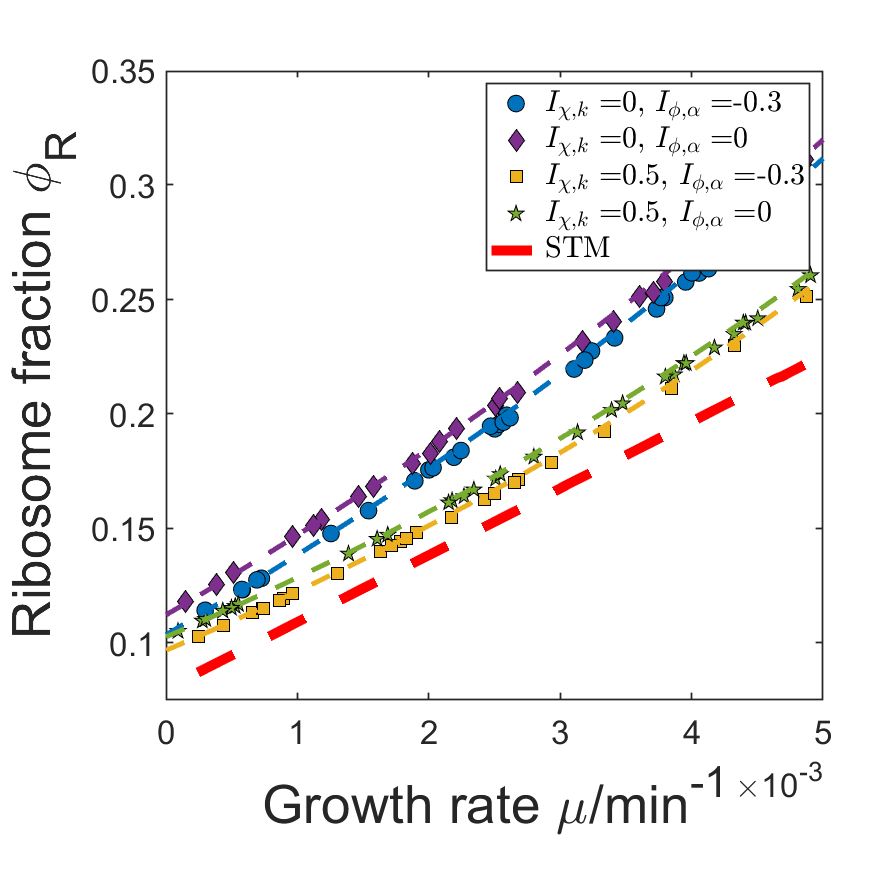

%%%plot
load muphi_large.mat

fig=figure;
set(fig,'Position',[300 100 700 700]);

ax1=axes('position', [0.19 0.2 0.75 0.72]);

p=zeros(3,3);


i_0=0;
i_1=[0 0.5 ];
for Ikx=i_1
i_0=i_0+1;

j_0=0;
j_1=[-0.3 0];
for Ialpx=j_1
j_0=j_0+1;

muphi_0=muphi;


pp=find(muphi_0(:,3)<Ikx-0.02|muphi_0(:,3)>Ikx+0.02);
muphi_0(pp,:)=[];
pp=find(muphi_0(:,5)<Ialpx-0.01|muphi_0(:,5)>Ialpx+0.01);
muphi_0(pp,:)=[];
 

if i_0==1
    if j_0==1
    colors='#0072BD';
    shapes='o';
    else
    colors='#7E2F8E';
    shapes='d'; 
    end
else
    if j_0==1
    colors='#EDB120';
    shapes='s';
    else
    colors='#77AC30';
    shapes='p'; 
    end
end

p(i_0,j_0)=plot(muphi_0(1:70,1),muphi_0(1:70,2),shapes, ...
    "MarkerSize",10, ...
    'MarkerEdgeColor','black', ...
    'MarkerFaceColor',	colors,...
    'DisplayName',['$I_{\chi,k} = $',num2str(i_1(i_0)),', $I_{\phi,\alpha} = $',num2str(j_1(j_0))]) ;


hold on
end
end



hold on

%predication
rng('shuffle');
total=2e5;

var_chi=zeros(1,total);

i_0=0;
%i_1=[0.5 0.4  1.18 1.25 0.64 0.53 0.64];
i_1=[0 0.5];
for Ikx=i_1
i_0=i_0+1;

j_0=0;
j_1=[-0.3 0];
for Ialpx=j_1
j_0=j_0+1;
   

muphi_pre=IkxIak_sol_fun(total,Ikx,Ialpx,mean_keff,keff_R,mean_alpha,alphaR);
  
 

if i_0==1
    if j_0==1
    colors='#0072BD';
    else
    colors='#7E2F8E';
    end
else
    if j_0==1
    colors='#EDB120';
    else
    colors='#77AC30';
    end
end

plot(muphi_pre(:,1),muphi_pre(:,2),'--','LineWidth',3,'color',colors) 


hold on
end
end


%%%predication with STM
load muphi_stm.mat
p6=plot(muphi_stm(:,1),muphi_stm(:,2),'--',"LineWidth",6,'DisplayName','STM',"Color","red");

set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
xlabel('Growth rate \mu/min^{-1}','interpreter','tex','FontSize',32);
ylabel('Ribosome fraction \phi_R','interpreter','tex','FontSize',32);
axis([0 5e-3,0.0750  0.35])
hold on


legend([p(1,1) p(1,2) p(2,1) p(2,2) p6],'interpreter','Latex')
hold off

Random sampling and the resulting distributions.

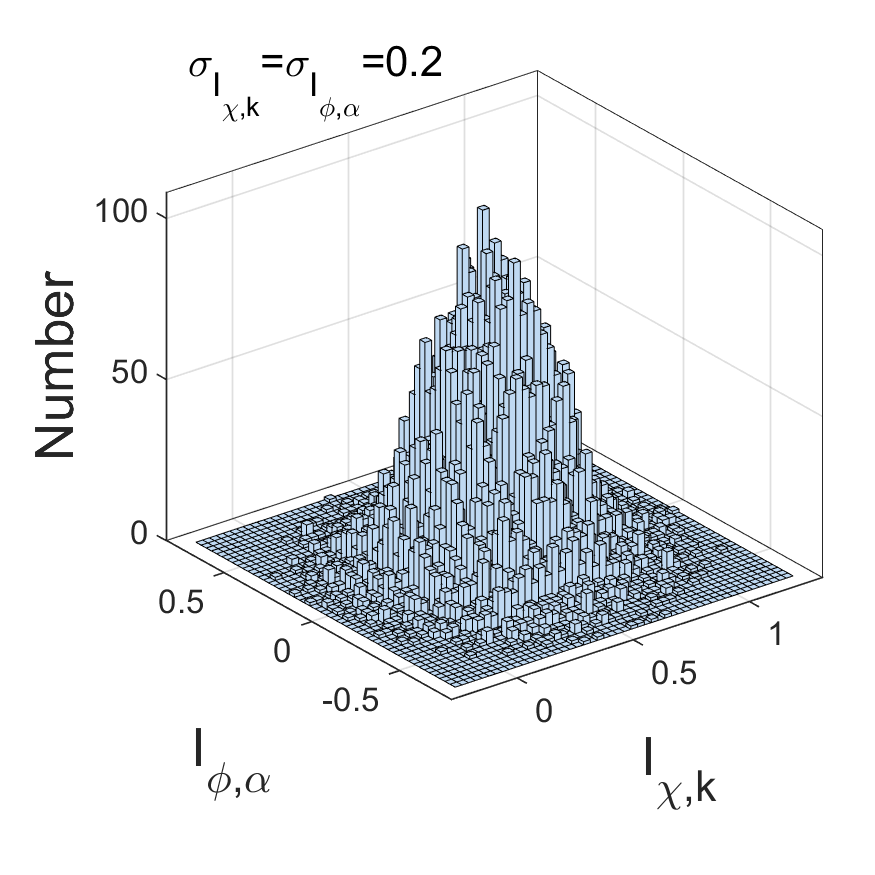


%%%%%sigma=0.2

mean_norm=[0.5 0];
sigma=[0.2^2,0;
       0,0.2^2];
temp1=sampling_2norm([muphi(:,3),muphi(:,5),(1:length(muphi(:,3)))'], ...
    mean_norm,sigma,0.1,1);
muphi_norm=muphi(temp1(:,3),:);
%normally sample data points from the simulation result

nperm=5000;
slope_all=zeros(nperm,1);
inter_all=zeros(nperm,1);
slope_large=zeros(nperm,1);
inter_large=zeros(nperm,1);

for i=1:nperm
temp1=muphi_norm(muphi_norm(:,1)>4.6e-3,:);
temp2=randperm(length(temp1(:,1)),10);
temp3=temp1(temp2,:);
temp4=polyfit(temp3(:,1),temp3(:,2),1);
slope_large(i)=temp4(1);
inter_large(i)=temp4(2);

temp5=muphi_norm(muphi_norm(:,1)<4.6e-3,:);
temp6=randperm(length(temp5(:,1)),10);
temp7=temp5(temp6,:);
temp8=polyfit([temp3(:,1);temp7(:,1)],[temp3(:,2);temp7(:,2)],1);
slope_all(i)=temp8(1);
inter_all(i)=temp8(2);

end




%plot the distribution of the data points
fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

hist3([muphi_norm(:,3),muphi_norm(:,5)],[50 50])

set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
xlabel('I_{\chi,k}','interpreter','tex','FontSize',32);
ylabel('I_{\phi,\alpha}','interpreter','tex','FontSize',32);
zlabel('Number','interpreter','tex','FontSize',32);
text(-0.25,0.75,145,"\sigma_{I_{\chi,k}}=\sigma_{I_{\phi,\alpha}}=0.2","FontSize",25)
box on
hold off

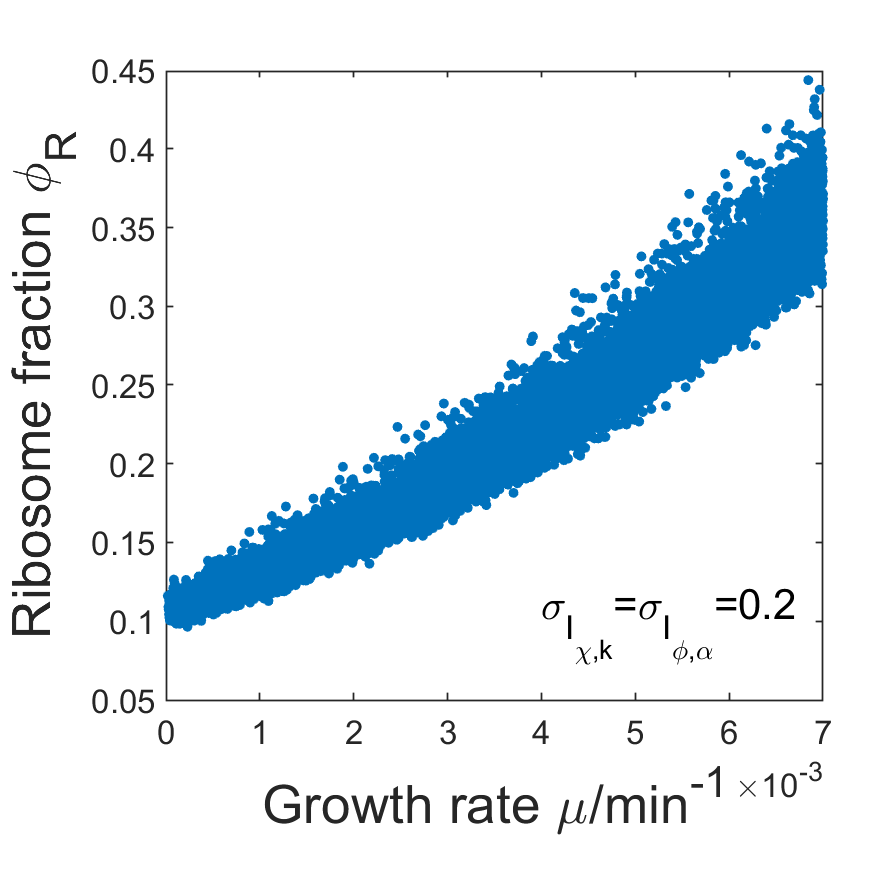




%plot the phR-mu of the data points
fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

scatter(muphi_norm(:,1),muphi_norm(:,2),'o', ...
    'MarkerEdgeColor','black', ...
    'MarkerFaceColor',[0 0.4470 0.7410], ...
    'MarkerEdgeAlpha',0, ...
    'MarkerFaceAlpha',1) ;

set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
xlabel('Growth rate \mu/min^{-1}','interpreter','tex','FontSize',32);
ylabel('Ribosome fraction \phi_R','interpreter','tex','FontSize',32);
text(4e-3,0.1,"\sigma_{I_{\chi,k}}=\sigma_{I_{\phi,\alpha}}=0.2","FontSize",25)

axis([0 7e-3,0.05 0.45])
box on

hold off


%fit the data and plot the destribution of RMSE
nperm=5000;
rmse=zeros(nperm,1);
parfor i=1:nperm
    
   temp1=randperm(length(muphi_norm(:,1)),20);
   muphi_fit=muphi_norm(temp1,:);

   [xData, yData] = prepareCurveData(muphi_fit(:,1),muphi_fit(:,2));
   ft = fittype( '(x+c1)/(c2*x+c3)', 'independent', 'x', 'dependent', 'y' );
   opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
   opts.Display = 'Off';
   opts.StartPoint = [0.964888535199277 0.157613081677548 0.970592781760616];
   [fitresult, gof] = fit( xData, yData, ft, opts );
   rmse(i)=gof.rmse;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


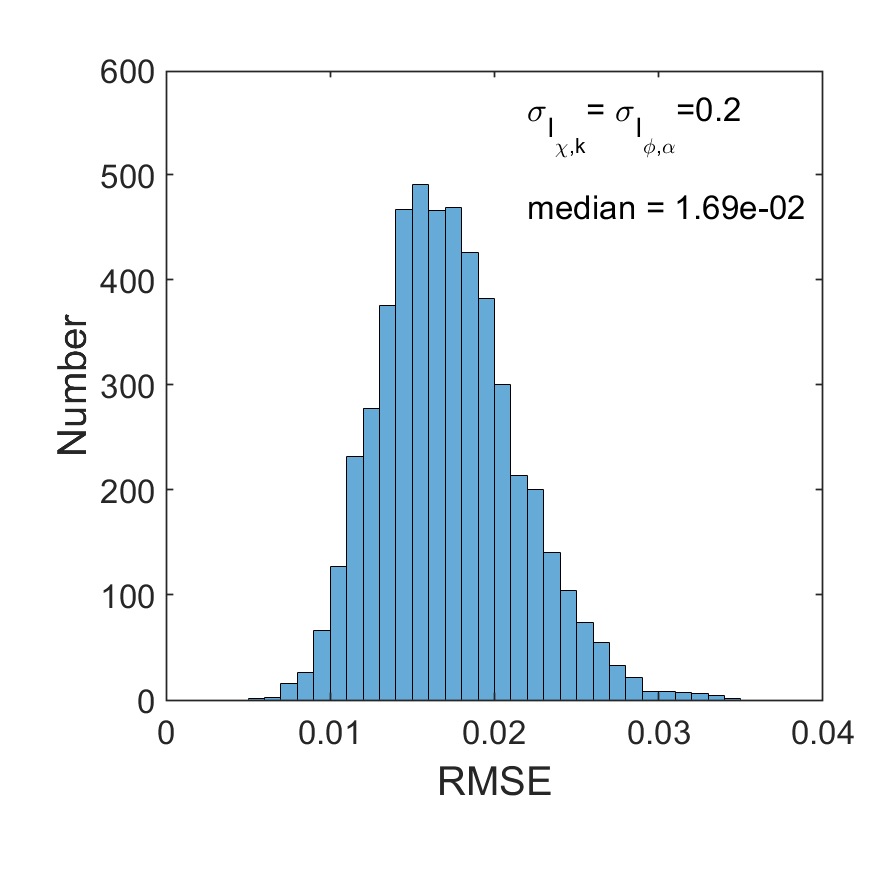


fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);
histogram(rmse)
xlabel('RMSE','interpreter','tex','FontSize',32);
ylabel('Number','interpreter','tex','FontSize',32);
text(0.022,550,"\sigma_{I_{\chi,k}}= \sigma_{I_{\phi,\alpha}}=0.2","FontSize",20);
text(0.022,470,['median = ',num2str(median(rmse),'%.2e')],"FontSize",20);
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
axis([0 0.04 0 600])
set(gca,'FontSize',20)
box on
hold off

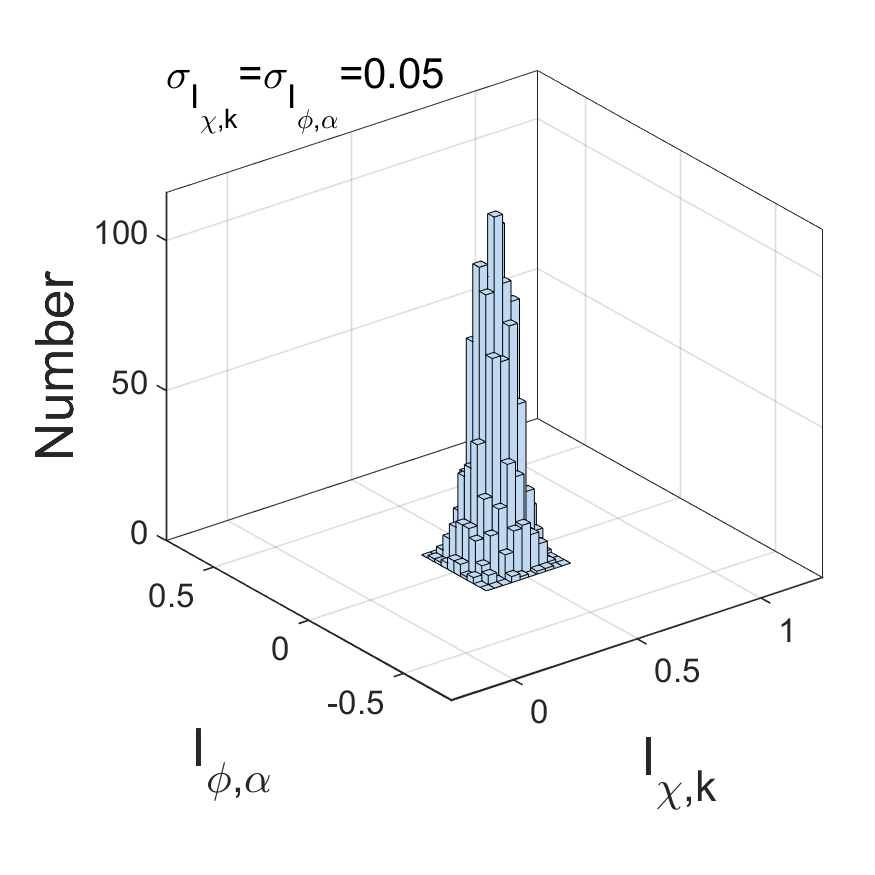





%%%%%sigma=0.05

mean_norm=[0.5 0];
sigma=[0.05^2,0;
       0,0.05^2];
temp1=sampling_2norm([muphi(:,3),muphi(:,5),(1:length(muphi(:,3)))'], ...
    mean_norm,sigma,0.05,1);
muphi_norm=muphi(temp1(:,3),:);
%normally sample data points from the simulation result

nperm=5000;
slope_all=zeros(nperm,1);
inter_all=zeros(nperm,1);
slope_large=zeros(nperm,1);
inter_large=zeros(nperm,1);

for i=1:nperm
temp1=muphi_norm(muphi_norm(:,1)>4.6e-3,:);
temp2=randperm(length(temp1(:,1)),10);
temp3=temp1(temp2,:);
temp4=polyfit(temp3(:,1),temp3(:,2),1);
slope_large(i)=temp4(1);
inter_large(i)=temp4(2);

temp5=muphi_norm(muphi_norm(:,1)<4.6e-3,:);
temp6=randperm(length(temp5(:,1)),10);
temp7=temp5(temp6,:);
temp8=polyfit([temp3(:,1);temp7(:,1)],[temp3(:,2);temp7(:,2)],1);
slope_all(i)=temp8(1);
inter_all(i)=temp8(2);

end




%plot the distribution of the data points
fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

hist3([muphi_norm(:,3),muphi_norm(:,5)],[10 10])

set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
xlabel('I_{\chi,k}','interpreter','tex','FontSize',32);
ylabel('I_{\phi,\alpha}','interpreter','tex','FontSize',32);
zlabel('Number','interpreter','tex','FontSize',32);
axis([-0.25 1.25,-0.75 0.75])
text(-0.25,0.75,150,"\sigma_{I_{\chi,k}}=\sigma_{I_{\phi,\alpha}}=0.05","FontSize",25)
box on
hold off

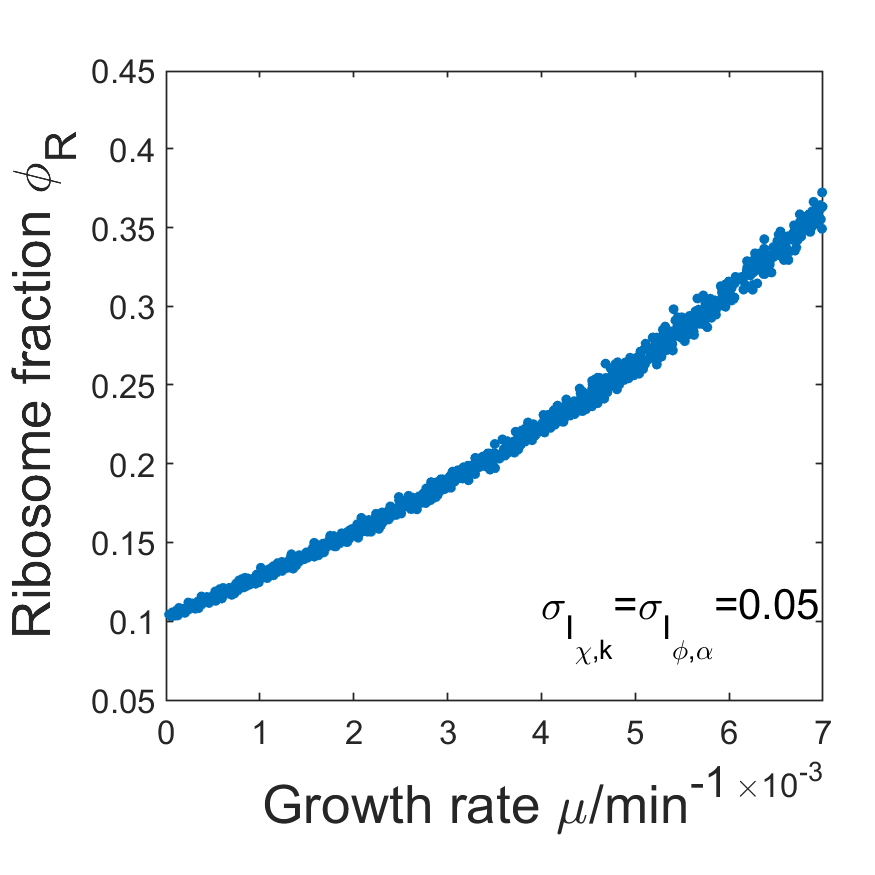




%plot the phR-mu of the data points
fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

scatter(muphi_norm(:,1),muphi_norm(:,2),'o', ...
    'MarkerEdgeColor','black', ...
    'MarkerFaceColor',[0 0.4470 0.7410], ...
    'MarkerEdgeAlpha',0, ...
    'MarkerFaceAlpha',1) ;

set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
xlabel('Growth rate \mu/min^{-1}','interpreter','tex','FontSize',32);
ylabel('Ribosome fraction \phi_R','interpreter','tex','FontSize',32);
text(4e-3,0.1,"\sigma_{I_{\chi,k}}=\sigma_{I_{\phi,\alpha}}=0.05","FontSize",25)

axis([0 7e-3,0.05 0.45])
box on

hold off

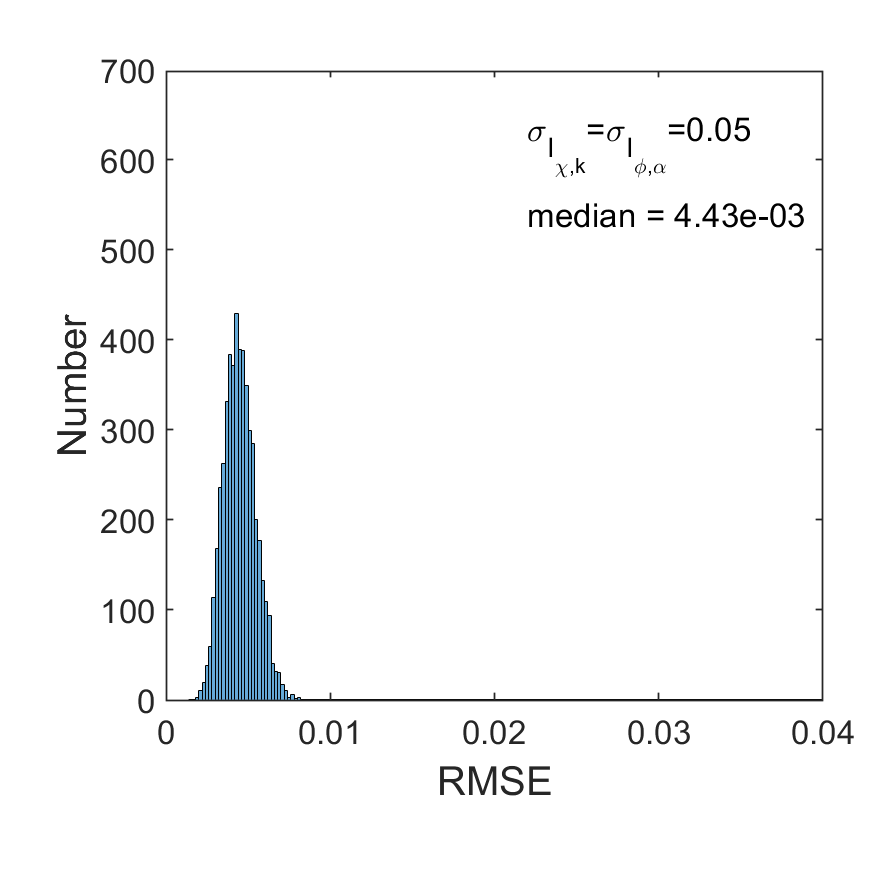



%fit the data and plot the destribution of RMSE
nperm=5000;
rmse=zeros(nperm,1);
parfor i=1:nperm
    
   temp1=randperm(length(muphi_norm(:,1)),20);
   muphi_fit=muphi_norm(temp1,:);

   [xData, yData] = prepareCurveData(muphi_fit(:,1),muphi_fit(:,2));
   ft = fittype( '(x+c1)/(c2*x+c3)', 'independent', 'x', 'dependent', 'y' );
   opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
   opts.Display = 'Off';
   opts.StartPoint = [0.964888535199277 0.157613081677548 0.970592781760616];
   [fitresult, gof] = fit( xData, yData, ft, opts );
   rmse(i)=gof.rmse;
end

fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);
histogram(rmse)
xlabel('RMSE','interpreter','tex','FontSize',32);
ylabel('Number','interpreter','tex','FontSize',32);
text(0.022,620,"\sigma_{I_{\chi,k}}=\sigma_{I_{\phi,\alpha}}=0.05","FontSize",20);
text(0.022,540,['median = ',num2str(median(rmse),'%.2e')],"FontSize",20);
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
axis([0 0.04 0 700])
set(gca,'FontSize',20)
box on
hold off

The prediction function.

function[muphi]=IkxIak_sol_fun(total,Ikx,Ialpx,mean_keff,kR,mean_alpha,alphaR)
  
muphi=zeros(total,6);


mR=1.4e6;%Da


phi0=0.08;



   chiR=0:1/(total-1):1;
   phiR=(mR*mean_alpha + mean_keff*phi0 + Ialpx*mR*mean_alpha + Ikx*mean_keff*phi0 + chiR*kR*phi0 - chiR*mean_keff*phi0 - Ikx*chiR*mean_keff*phi0)./(mean_keff + Ikx*mean_keff + chiR*kR - alphaR*mR - chiR*mean_keff + mR*mean_alpha - Ikx*chiR*mean_keff + Ialpx*mR*mean_alpha) - (alphaR*mR - chiR*kR + mR*mean_alpha + mean_keff*phi0 - sqrt(Ialpx^2*mR^2*mean_alpha^2 - 2*Ialpx*Ikx*chiR*mR*mean_keff*mean_alpha*phi0 + 2*Ialpx*Ikx*mR*mean_keff*mean_alpha*phi0 - 2*Ialpx*alphaR*mR^2*mean_alpha - 2*Ialpx*chiR*kR*mR*mean_alpha*phi0 + 2*Ialpx*chiR*kR*mR*mean_alpha - 2*Ialpx*chiR*mR*mean_keff*mean_alpha*phi0 + 2*Ialpx*mR^2*mean_alpha^2 + 2*Ialpx*mR*mean_keff*mean_alpha*phi0 + Ikx^2*chiR.^2*mean_keff^2*phi0^2 - 2*Ikx^2*chiR*mean_keff^2*phi0^2 + Ikx^2*mean_keff^2*phi0^2 + 2*Ikx*alphaR*chiR*mR*mean_keff*phi0 - 2*Ikx*alphaR*mR*mean_keff*phi0 - 2*Ikx*chiR.^2*kR*mean_keff*phi0^2 + 2*Ikx*chiR.^2*kR*mean_keff*phi0 + 2*Ikx*chiR.^2*mean_keff^2*phi0^2 + 2*Ikx*chiR*kR*mean_keff*phi0^2 - 2*Ikx*chiR*kR*mean_keff*phi0 - 2*Ikx*chiR*mR*mean_keff*mean_alpha*phi0 - 4*Ikx*chiR*mean_keff^2*phi0^2 + 2*Ikx*mR*mean_keff*mean_alpha*phi0 + 2*Ikx*mean_keff^2*phi0^2 + alphaR^2*mR^2 + 2*alphaR*chiR*kR*mR*phi0 - 2*alphaR*chiR*kR*mR + 2*alphaR*chiR*mR*mean_keff*phi0 - 2*alphaR*mR^2*mean_alpha - 2*alphaR*mR*mean_keff*phi0 + chiR.^2*kR^2*phi0^2 - 2*chiR.^2*kR^2*phi0 + chiR.^2*kR^2 - 2*chiR.^2*kR*mean_keff*phi0^2 + 2*chiR.^2*kR*mean_keff*phi0 + chiR.^2*mean_keff^2*phi0^2 - 2*chiR*kR*mR*mean_alpha*phi0 + 2*chiR*kR*mR*mean_alpha + 2*chiR*kR*mean_keff*phi0^2 - 2*chiR*kR*mean_keff*phi0 - 2*chiR*mR*mean_keff*mean_alpha*phi0 - 2*chiR*mean_keff^2*phi0^2 + mR^2*mean_alpha^2 + 2*mR*mean_keff*mean_alpha*phi0 + mean_keff^2*phi0^2) + Ialpx*mR*mean_alpha + Ikx*mean_keff*phi0 + chiR*kR*phi0 - chiR*mean_keff*phi0 - Ikx*chiR*mean_keff*phi0)./(2*(mean_keff + Ikx*mean_keff + chiR*kR - alphaR*mR - chiR*mean_keff + mR*mean_alpha - Ikx*chiR*mean_keff + Ialpx*mR*mean_alpha));
   mu= - alphaR - (chiR.*kR.*(phi0./phiR - 1))/mR;

 
   temp1(1:total)=Ikx;
   temp2(1:total)=Ialpx;
   muphi=[mu;phiR;temp1;temp2;chiR;zeros(1,total)];
   muphi=muphi';

pp=find(muphi(:,1)<0);
muphi(pp,:)=[];

pp=find(muphi(:,2)<0);
muphi(pp,:)=[];

pp=find(muphi(:,2)>1);
muphi(pp,:)=[];


end